**Frequency Vs Throughput Vs Monitoring area**

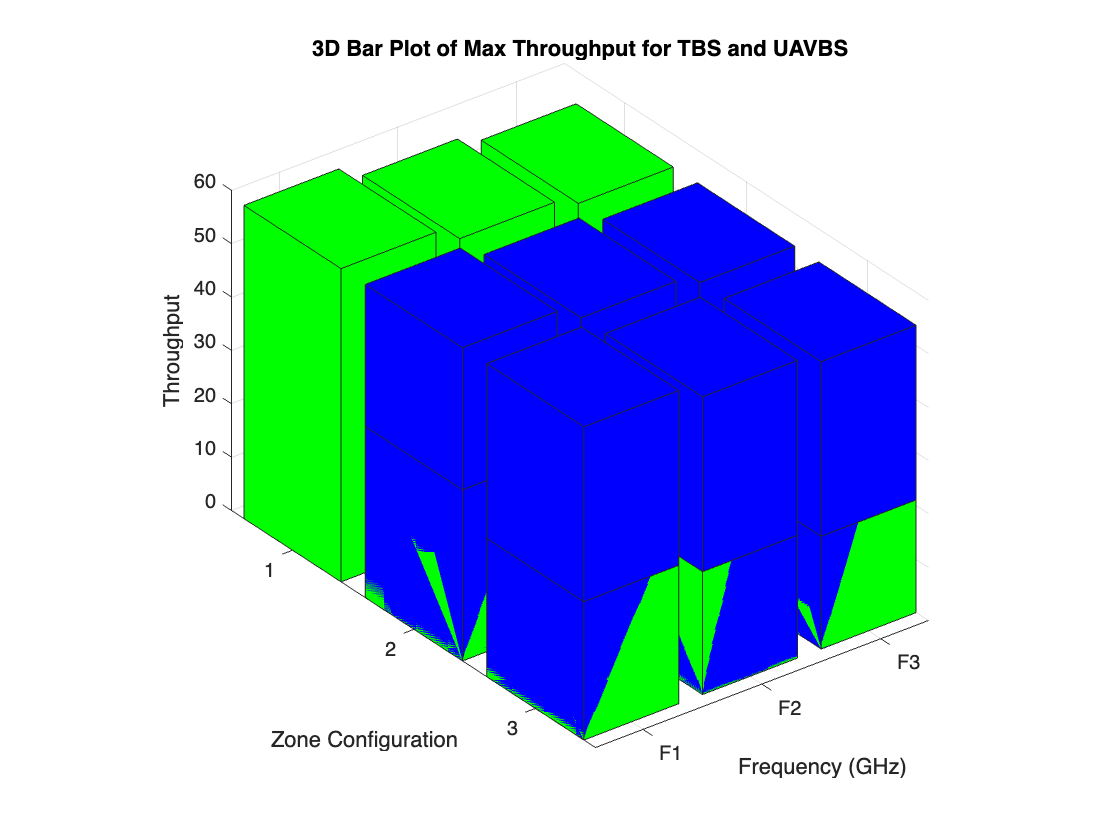

%For UAVBS

f1_U_Z1 = load('f1_U_Z1_avgDr.mat');
f1_U_Z1Max = f1_U_Z1.f1_U_Z1_avgDr;

f1_U_Z2 = load('f1_U_Z2_avgDr.mat');
f1_U_Z2Max = f1_U_Z2.f1_U_Z2_avgDr;

f1_U_Z3 = load('f1_U_Z3_avgDr.mat');
f1_U_Z3Max = f1_U_Z3.f1_U_Z3_avgDr;


f2_U_Z1 = load('f2_U_Z1_avgDr.mat');
f2_U_Z1Max = f2_U_Z1.f2_U_Z1_avgDr;

f2_U_Z2 = load('f2_U_Z2_avgDr.mat');
f2_U_Z2Max = f2_U_Z2.f2_U_Z2_avgDr;

f2_U_Z3 = load('f2_U_Z3_avgDr.mat');
f2_U_Z3Max = f2_U_Z3.f2_U_Z3_avgDr;



f3_U_Z1 = load('f3_U_Z1_avgDr.mat');
f3_U_Z1Max = f3_U_Z1.f3_U_Z1_avgDr;

f3_U_Z2 = load('f3_U_Z2_avgDr.mat');
f3_U_Z2Max = f3_U_Z2.f3_U_Z2_avgDr;

f3_U_Z3 = load('f3_U_Z3_avgDr.mat');
f3_U_Z3Max = f3_U_Z3.f3_U_Z3_avgDr;


%For TBS

f1_T_Z1 = load('f1_T_Z1_avgDr.mat');
f1_T_Z1Max = f1_T_Z1.f1_T_Z1_avgDr;

f1_T_Z2 = load('f1_T_Z2_avgDr.mat');
f1_T_Z2Max = f1_T_Z2.f1_T_Z2_avgDr;

f1_T_Z3 = load('f1_T_Z3_avgDr.mat');
f1_T_Z3Max = f1_T_Z3.f1_T_Z3_avgDr;


f2_T_Z1 = load('f2_T_Z1_avgDr.mat');
f2_T_Z1Max = f2_T_Z1.f2_T_Z1_avgDr;

f2_T_Z2 = load('f2_T_Z2_avgDr.mat');
f2_T_Z2Max = f2_T_Z2.f2_T_Z2_avgDr;

f2_T_Z3 = load('f2_T_Z3_avgDr.mat');
f2_T_Z3Max = f2_T_Z3.f2_T_Z3_avgDr;



f3_T_Z1 = load('f3_T_Z1_avgDr.mat');
f3_T_Z1Max = f3_T_Z1.f3_T_Z1_avgDr;

f3_T_Z2 = load('f3_T_Z2_avgDr.mat');
f3_T_Z2Max = f3_T_Z2.f3_T_Z2_avgDr;

f3_T_Z3 = load('f3_T_Z3_avgDr.mat');
f3_T_Z3Max = f3_T_Z3.f3_T_Z3_avgDr;

uavbs_MaxDr = [f1_U_Z1Max, f2_U_Z1Max, f3_U_Z1Max;f1_U_Z2Max, f2_U_Z2Max, f3_U_Z2Max; f1_U_Z3Max, f2_U_Z3Max, f3_U_Z3Max];
tbs_MaxDr = [f1_T_Z1Max, f2_T_Z1Max, f3_T_Z1Max;f1_T_Z2Max, f2_T_Z2Max, f3_T_Z2Max; f1_T_Z3Max, f2_T_Z3Max, f3_T_Z3Max];

freq = {'F1','F2','F3'};
zones = [1,2,3];
% uavbs_MaxDr = uavbs_MaxDr(2,:);
% 
% tbs_MaxDr = tbs_MaxDr(2,:);
figure;
bar3(uavbs_MaxDr,'blue');
hold on 
bar3(tbs_MaxDr,'green');
set(gca, 'XTickLabel', freq, 'YTickLabel', zones);
xlabel('Frequency (GHz)');
ylabel('Zone Configuration');
zlabel('Throughput');
%legend('Same throughput','Different throughput')
%legend('UAVBS','TBS')
title('3D Bar Plot of Max Throughput for TBS and UAVBS');
hold off

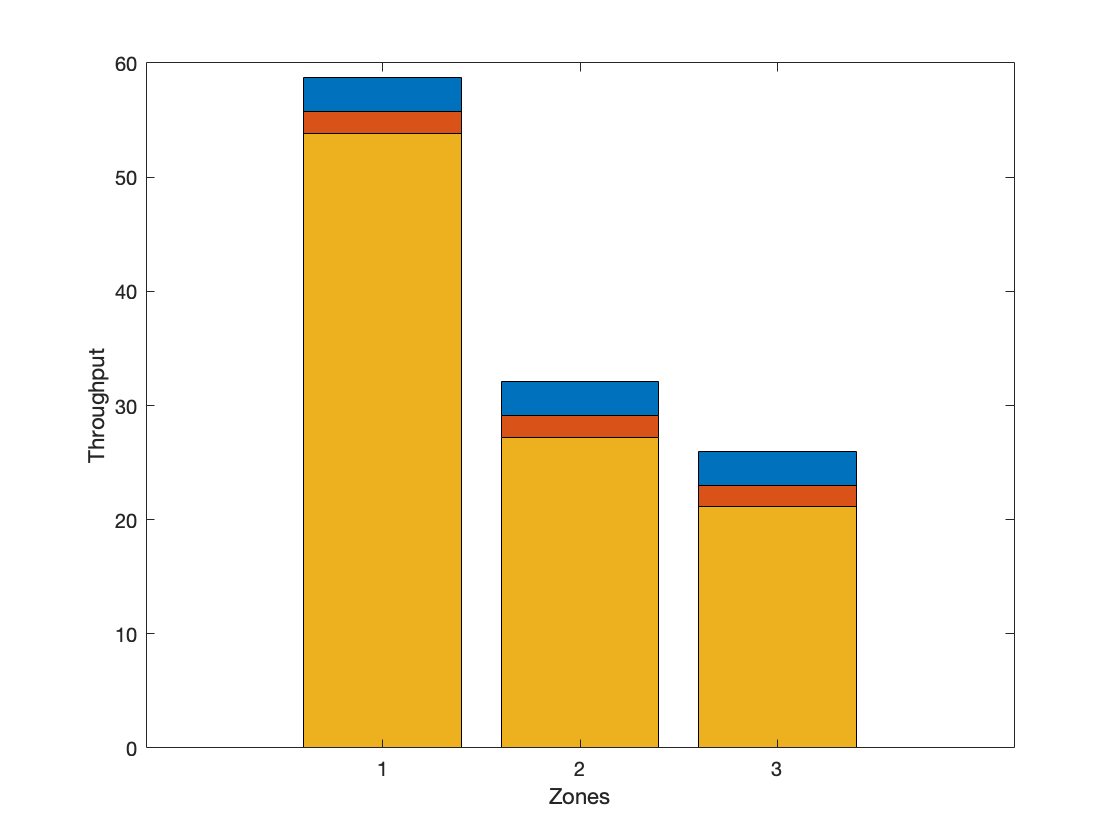

utbs_maxDr_z1 = [f1_U_Z1Max, f2_U_Z1Max, f3_U_Z1Max];
utbs_maxDr_z2 = [f1_U_Z2Max, f2_U_Z2Max, f3_U_Z2Max];
utbs_maxDr_z3 = [f1_U_Z3Max, f2_U_Z3Max, f3_U_Z3Max];

tbs_maxDr_z1 = [f1_T_Z1Max, f2_T_Z1Max, f3_T_Z1Max];
tbs_maxDr_z2 = [f1_T_Z2Max, f2_T_Z2Max, f3_T_Z2Max];
tbs_maxDr_z3 = [f1_T_Z3Max, f2_T_Z3Max, f3_T_Z3Max];

utbs_maxDr_f1 = [f1_U_Z1Max,f1_U_Z2Max,f1_U_Z3Max];
utbs_maxDr_f2 = [f2_U_Z1Max,f2_U_Z2Max,f2_U_Z3Max];
utbs_maxDr_f3 = [f3_U_Z1Max,f3_U_Z2Max,f3_U_Z3Max];

tbs_maxDr_f1 = [f1_T_Z1Max,f1_T_Z2Max,f1_T_Z3Max];
tbs_maxDr_f2 = [f2_T_Z1Max,f2_T_Z2Max,f2_T_Z3Max];
tbs_maxDr_f3 = [f3_T_Z1Max,f3_T_Z2Max,f3_T_Z3Max];

figure 
bar(tbs_maxDr_f1)
hold on
bar(tbs_maxDr_f2)
hold on
bar(tbs_maxDr_f3)
xlabel('Zones');
ylabel('Throughput');

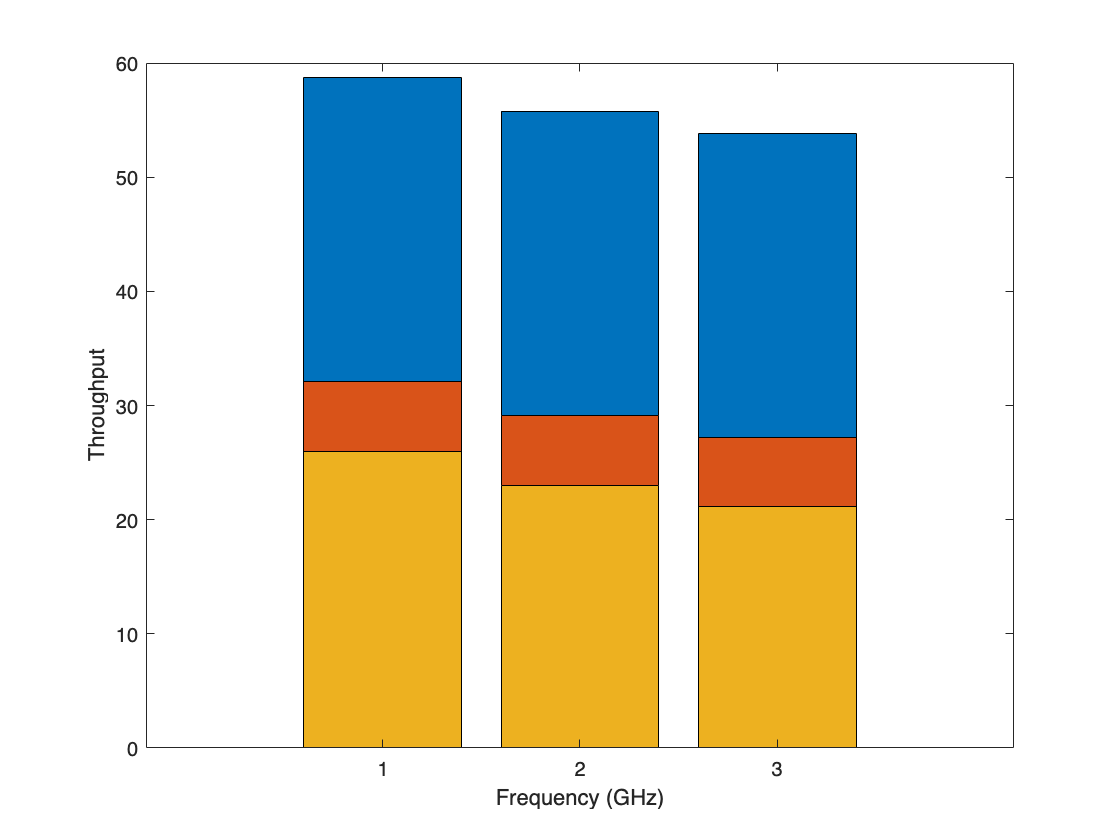

figure 
bar(tbs_maxDr_z1)
hold on
bar(tbs_maxDr_z2)
hold on
bar(tbs_maxDr_z3)
xlabel('Frequency (GHz)');
ylabel('Throughput');

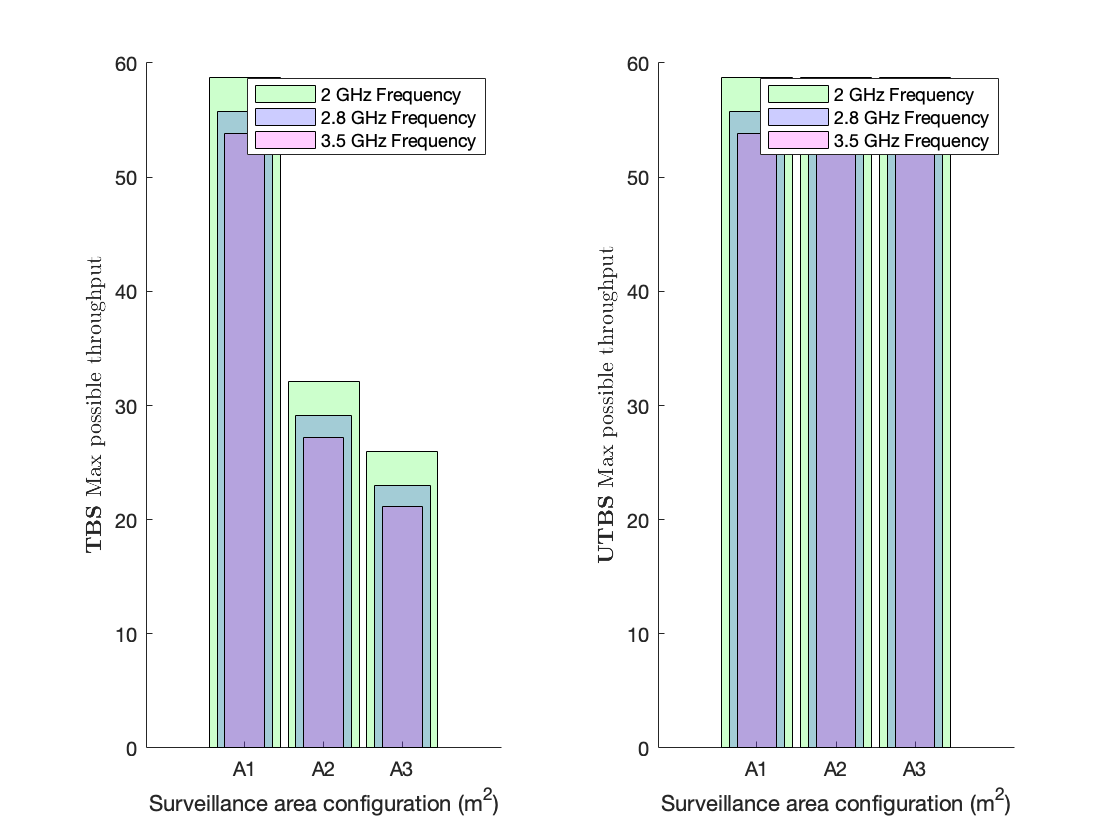


figure;
tiledlayout(1,2); % 1 row, 2 columns layout

% Define x-axis labels
req_spec = [1 2 3]; % Positions of the x-axis ticks
x_labels = {'A1', 'A2', 'A3'}; % Custom labels

% TBS Figure
nexttile;
hold on;
xticks(req_spec); % Set the tick positions
xticklabels(x_labels); % Set custom tick labels

hbh(1) = bar(req_spec, tbs_maxDr_f1, 'BarWidth', 0.9, 'FaceColor', 'g'); 
hbh(2) = bar(req_spec, tbs_maxDr_f2, 'BarWidth', 0.7, 'FaceColor', 'b');
hbh(3) = bar(req_spec, tbs_maxDr_f3, 'BarWidth', 0.5, 'FaceColor', 'm');

for k = 1:numel(hbh)
    hbh(k).EdgeColor = 'k';
    hbh(k).FaceAlpha = 0.2;
end

legend('2 GHz Frequency', '2.8 GHz Frequency', '3.5 GHz Frequency');
xlabel('Surveillance area configuration (m^2)');
ylabel('\textbf{TBS}~Max possible throughput', 'Interpreter', 'latex');

%title('TBS Max Throughput');

% UTBS Figure
nexttile;
hold on;
xticks(req_spec); % Set the tick positions
xticklabels(x_labels); % Set custom tick labels

hbh2(1) = bar(req_spec, utbs_maxDr_f1, 'BarWidth', 0.9, 'FaceColor', 'g'); 
hbh2(2) = bar(req_spec, utbs_maxDr_f2, 'BarWidth', 0.7, 'FaceColor', 'b');
hbh2(3) = bar(req_spec, utbs_maxDr_f3, 'BarWidth', 0.5, 'FaceColor', 'm');

for k = 1:numel(hbh2)
    hbh2(k).EdgeColor = 'k';
    hbh2(k).FaceAlpha = 0.2;
end

legend('2 GHz Frequency', '2.8 GHz Frequency', '3.5 GHz Frequency');
xlabel('Surveillance area configuration (m^2)');
ylabel('\textbf{UTBS}~Max possible throughput', 'Interpreter', 'latex');


%title('UTBS Max Throughput');


**Surveillance time Vs Payload**

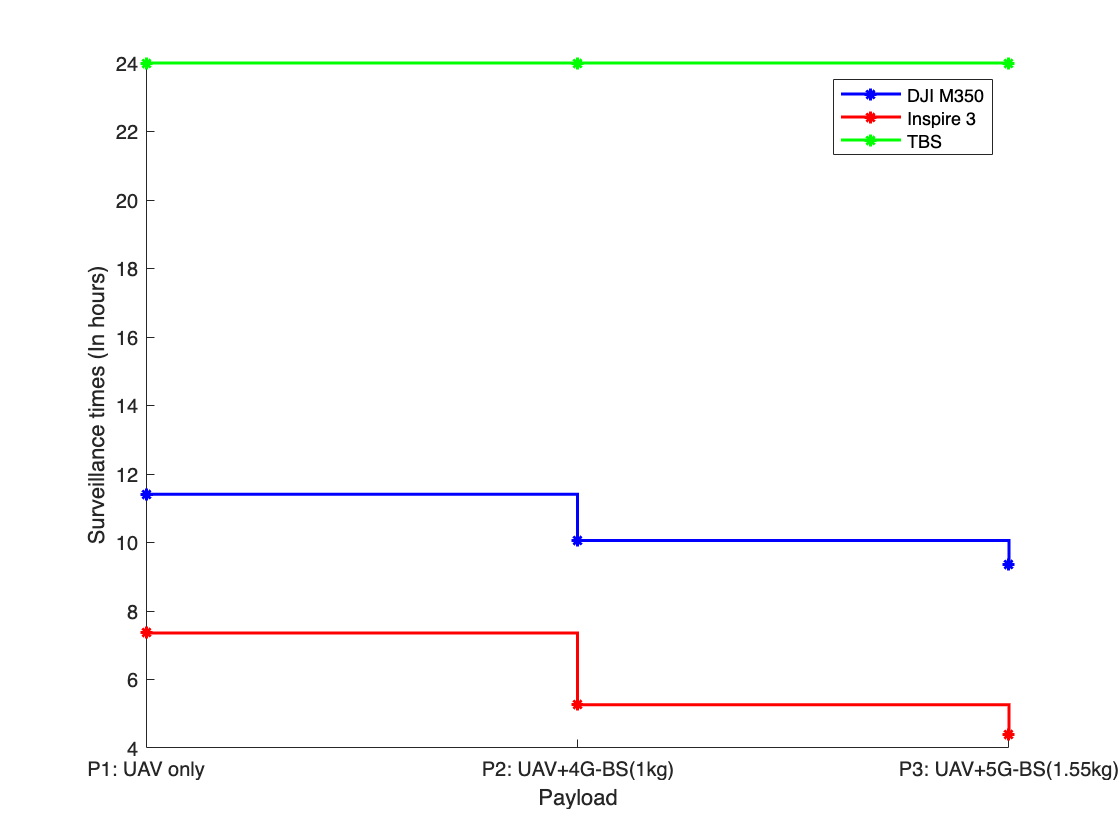

tbs_serv_time = 23.9988;
tbs = [tbs_serv_time tbs_serv_time tbs_serv_time];
m350_l2 = [11.41 10.06 9.35]; % In hours
insp_L2 = [7.36 5.26 4.38];% In hours
payloads = 1:3;  % Assuming payloads are labeled as 1, 2, and 3

% Plot stairs plot for D1 model
figure;
hold on;  % Hold on to plot both on the same figure
stairs(payloads, m350_l2, 'b-*', 'LineWidth', 1.5);  % Blue line 
stairs(payloads, insp_L2, 'r-*', 'LineWidth', 1.5);  % Red line
stairs(payloads,tbs,'g-*','LineWidth', 1.5); 

legend('DJI M350','Inspire 3','TBS')
xticklabels({'P1: UAV only', 'P2: UAV+4G-BS(1kg)', 'P3: UAV+5G-BS(1.55kg)'});
xticks([1 2 3])
xlabel('Payload')
ylabel('Surveillance times (In hours)')
hold off;

**Connectivity downtime Vs Docking station locations for Single zone**

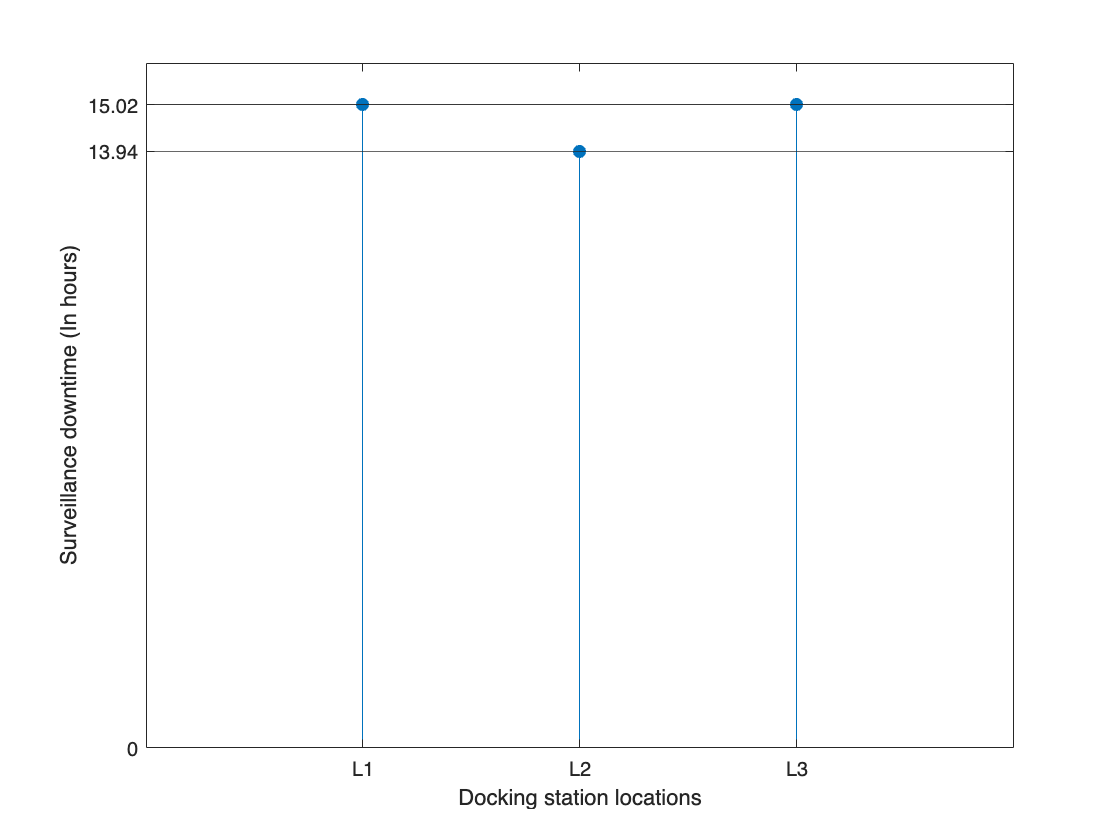

l1_loc = [5000 0 0];
l2_loc = [5000 2500 0];
l3_loc = [5000 5000 0];

l1_downtime = 15.02;%In hrs in 24hrs
l2_downtime = 13.94;%In hrs in 24hrs
l3_downtime = 15.02;%In hrs in 24hrs
tbs_downtime = 0.13/60;%In hrs in 24hrs
downtime = [l1_downtime l2_downtime l3_downtime];
figure 
stem(downtime,'filled');
xlim([0 4])
%ylim([0 20])
xlabel('Docking station locations')
ylabel('Surveillance downtime (In hours)')
xticks([1 2 3])
xticklabels({'L1', 'L2', 'L3'});
yticks([0 13.94 15.02])
yline(downtime)

% yticklabels({'15.02', '13.94'})
% yticks([15 13])

%legend('Docking station downtime')